Baudrate = 115200;
serialportlist

ans = "COM3"

RpLidar = serialport("COM3", Baudrate, "Timeout", 1)

RpLidar =   Serialport with properties:

                 Port: "COM3"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


setDTR(RpLidar,false)
RpLidar.FlowControl

ans = "none"

% Reset (leave protected mode)
resetStr = 'A540'

resetStr = 'A540'

resetStrData = sscanf(resetStr, '%2x')

resetStrData =    165
    64


write(RpLidar,resetStrData,"uint8")
read(RpLidar, 5, "uint8")

ans =     82    80    32    76    73


% Start scan
startStr = 'A521'

startStr = 'A521'

startStrData = sscanf(startStr, '%2x')

startStrData =    165
    33


write(RpLidar,startStr,"uint8")
scandata = read(RpLidar, 30, "uint8")

scandata =     68    65    82    32    83   121   115   116   101   109    46    13    10    70   105   114   109   119    97   114   101    32    86   101   114    32    49    46    50    55


dec2bin(scandata, 8)

ans = 30×8 char array
    '01000100'
    '01000001'
    '01010010'
    '00100000'
    '01010011'
    '01111001'
    '01110011'
    '01110100'
    '01100101'
    '01101101'
    '00101110'
    '00001101'
    '00001010'
    '01000110'
    '01101001'
    '01110010'
    '01101101'
    '01110111'
    '01100001'
    '01110010'
    '01100101'
    '00100000'
    '01010110'
    '01100101'
    '01110010'
    '00100000'
    '00110001'
    '00101110'
    '00110010'
    '00110111'



stopStr = 'A525'
stopStrData = sscanf(stopStr, '%2x')
write(RpLidar,stopStr,"uint8")
readStop = read(RpLidar, 8, "uint8")
dec2hex(readStop)

% health
str = 'A552';
data = sscanf(str, '%2x');
hexStrWriteData = dec2hex(data)

write(RpLidar, data, "uint8");
readData = read(RpLidar, 3,"uint8");
hexStr = dec2hex(readData)


getInfoStr = 'A550'
getInfoStrData = sscanf(getInfoStr, '%2x')
write(RpLidar,getInfoStrData,"uint8")
readInfo = read(RpLidar, 20,"uint8")
hexStr = dec2hex(readInfo)


start = randi([40, 50],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end
ranges

ranges =     48    49    48    49    49    48    47    47    48    49    48    49    50    50    51    50    50    51    52    53    53    52    53    54    55    56    57    57    57    56    57    56    55    54    53    54    55    54    55    54    54    54    55    56    55    55    55    55    56    57




angles = linspace(-pi/2, pi/2, numel(ranges))

angles =    -1.5708   -1.5620   -1.5533   -1.5445   -1.5358   -1.5270   -1.5183   -1.5095   -1.5008   -1.4920   -1.4833   -1.4745   -1.4658   -1.4570   -1.4483   -1.4395   -1.4308   -1.4220   -1.4133   -1.4045   -1.3958   -1.3870   -1.3783   -1.3695   -1.3608   -1.3520   -1.3433   -1.3345   -1.3258   -1.3170   -1.3083   -1.2995   -1.2908   -1.2820   -1.2733   -1.2645   -1.2558   -1.2470   -1.2383   -1.2295   -1.2208   -1.2120   -1.2033   -1.1945   -1.1858   -1.1770   -1.1683   -1.1595   -1.1508   -1.1420


scan = lidarScan(ranges, angles)

scan =   lidarScan with properties:

       Ranges: [360×1 double]
       Angles: [360×1 double]
    Cartesian: [360×2 double]
        Count: 360


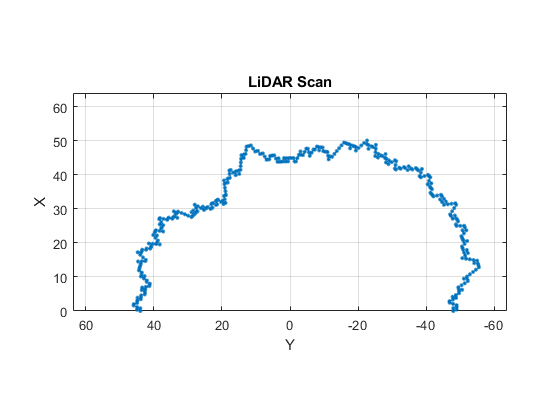

plot(scan)